licz=[-20 4];
licz_minus = [20 -4];
mian=[6 5 1];
G=tf(licz,mian);
G_minus = tf(licz_minus, mian)

G_minus =
 
     20 s - 4
  ---------------
  6 s^2 + 5 s + 1
 
Continuous-time transfer function.
Model Properties


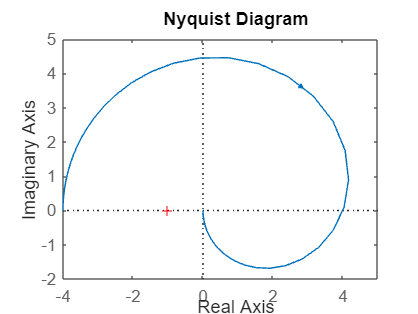

plotoptions= nyquistoptions('cstprefs') ;   % default options
plotoptions.ShowFullContour = 'off';        % exclude negative frequencies
nyquist(G_minus,plotoptions)

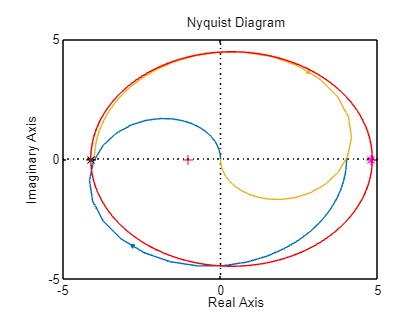

m1 = -4.10^(-1); 
m2 = 4.80^(-1);
hold on
P = nyquistoptions;
P.ShowFullContour = 'off';
nyquist(G_minus,P)
plot(1/m1, 0, 'k*')
plot(1/m2, 0, 'm*')
xlim([-5 5])
ylim([-5 5])
circle(0.35,0,4.47);
saveas(gcf,'1.png')

m1 = -4.10^(-1) 

m1 = -0.2439

m2 = 4.80^(-1)

m2 = 0.2083


[A,b,c,d] = tf2ss(licz_minus,mian);
m0 = 0.05;

macierz = A+b*m0*c

macierz =    -0.6667   -0.2000
    1.0000         0


wlasne = eig(macierz)

wlasne =   -0.3333 + 0.2981i
  -0.3333 - 0.2981i


if length(wlasne > 0) == 2
    num2str(m0)
end

ans = '0.05'

eig(A)

ans =    -0.5000
   -0.3333


function h = circle(x,y,r)
hold on
th = 0:pi/50:2*pi;
xunit = r * cos(th) + x;
yunit = r * sin(th) + y;
h = plot(xunit, yunit, 'r-');
hold off
end